clear; 
close all; clc; 
filename = '07-Feb-2025 09_35_19.txt';
fileID = fopen(filename, 'r');
data = textscan(fileID, '%s', 'Delimiter', '\n');
fclose(fileID);
lines = data{1};
disp(lines);

    {'Sample→Time→Encoder 1 Pos→Encoder 2 Pos→Control Effort'}
    {'1→0.001→0→-4→0'                                        }
    {'2→0.002→0→-4→0'                                        }
    {'3→0.003→1→-4→0'                                        }
    {'4→0.004→2→-4→0'                                        }
    {'5→0.005→3→-4→0'                                        }
    {'6→0.006→4→-4→0'                                        }
    {'7→0.007→5→-4→0'                                        }
    {'8→0.009→5→-4→0'                                        }
    {'9→0.01→6→-4→0'                                         }
    {'10→0.011→6→-4→0'                                       }
    {'11→0.012→6→-4→0'                                       }
    {'12→0.013→7→-4→0'                                       }
    {'13→0.014→7→-4→0'                                       }
    {'14→0.015→7→-5→0'                                       }
    {'15→0.016→7→-5→0'                                 



plot(time,enc1)

Unrecognized function or variable 'time'.

grid on 
box on


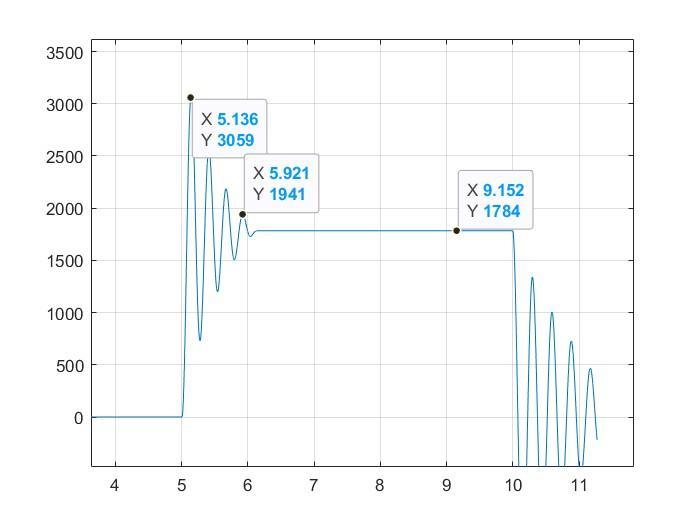

clear; clc; close all;
% PART 1
U = 0.6;
% hardcoded from graph
n = 4;
y_0 = 3059;
t_0 = 5.136;
y_n = 1941;
t_n = 5.921;
y_inf = 1784;

w_hat_d = 2*pi*(n/(t_n - t_0));

beta_w_n = 1/(t_n - t_0)*log((y_0 - y_inf)/(y_n - y_inf));

w_hat_n = norm(w_hat_d, beta_w_n);

beta_hat = beta_w_n/w_hat_n;

U
y_inf

k_hat = U/y_inf
m_hat = k_hat/(w_hat_n^2) % m1
d_hat = k_hat*(2*beta_hat/w_hat_n)% d1


clear; clc; close all;
load('Find_k1.mat')

% PART 2
% looking after the oscillations for the k1 value

plot(time,target_v,'--'); hold on
plot(time,duty)
plot(time,enc1)

legend('target_v', 'duty', 'enc1')

grid on 
box on

% hard coding values 
disp = 3475 % disp from the enc1 (counts_
force = 491 % voltage (from duty cycle)


k1 = force/disp

clear; clc; close all; 

% PART 3
% held m1 in place, applied unknown force onto m2
% option: isolating for k2
load('test3_holding_m1_econder1_hold_07-Feb-2025 09_35_19.mat')


plot(time,target_v,'--'); hold on
plot(time,duty)
plot(time,enc1)

legend('target_v', 'duty', 'enc1')

grid on 
box on


U = 0.6;
% hardcoded from graph
n = 4;
y_0 = 3087;
t_0 = 5.147;
y_n = 1933;
t_n = 5.911;
y_inf = 1784;

w_hat_d = 2*pi*(n/(t_n - t_0));
beta_w_n = 1/(t_n - t_0)*log((y_0 - y_inf)/(y_n - y_inf));
w_hat_n = norm(w_hat_d, beta_w_n);
beta_hat = beta_w_n/w_hat_n;

k1 = 0.1413 % from part 2

k_hat = 3.3632e-04 - k1 % k2
m2 =  (k_hat) *(1/w_hat_d)

d2 = k_hat* 2 * (2*beta_hat/m_hat) % d2


k1 = 0.1413
k2 = 0.2752
k_hat = 3.3632e-04